check =   -0.2652 - 0.2652i   0.0000 + 0.0000i  -0.4419 + 0.1768i  -0.6187 + 0.0884i
   0.2185 - 0.0625i  -0.2648 + 0.2274i   0.2258 - 0.1143i  -0.1317 - 0.1971i
  -0.1250 + 0.0732i   0.1509 - 0.0625i  -0.0518 - 0.0884i  -0.1875 + 0.1509i
  -0.0124 + 0.0625i  -0.0951 + 0.2472i   0.2258 + 0.1685i  -0.2338 + 0.0817i
  -0.0884 + 0.2652i   0.0884 + 0.0884i   0.0884 + 0.0000i   0.0000 + 0.1768i
   0.1892 + 0.0625i  -0.1773 - 0.2338i  -0.1301 - 0.2393i   0.0028 - 0.0140i
   0.0518 - 0.1768i   0.0259 - 0.0625i   0.1250 + 0.1616i  -0.0625 - 0.0991i
  -0.0418 - 0.0625i  -0.1430 - 0.1183i   0.0051 - 0.0332i   0.2274 + 0.0338i
  -0.2652 + 0.0884i  -0.1768 - 0.3536i  -0.0884 + 0.1768i  -0.0884 + 0.0884i
   0.0832 - 0.0625i   0.2648 + 0.1994i  -0.1008 - 0.1143i  -0.2950 + 0.1971i


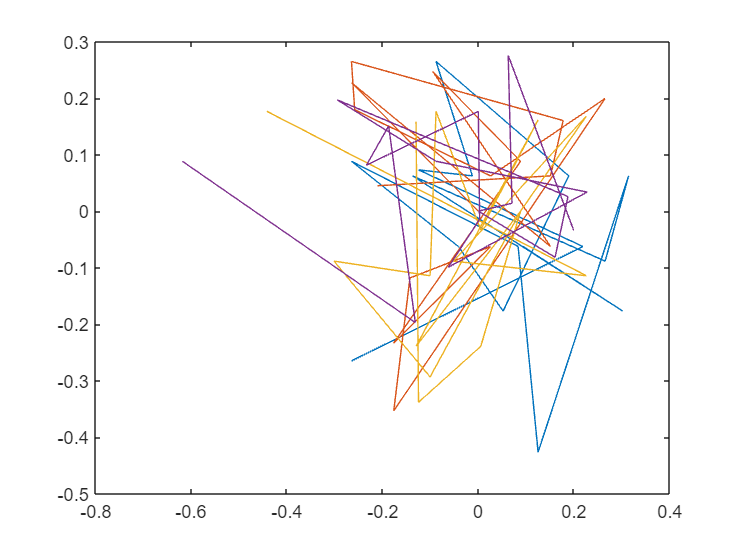

dtime =   -0.2652 - 0.2652i   0.0000 + 0.0000i  -0.4419 + 0.1768i  -0.6187 + 0.0884i
   0.2185 - 0.0625i  -0.2648 + 0.2274i   0.2258 - 0.1143i  -0.1317 - 0.1971i
  -0.1250 + 0.0732i   0.1509 - 0.0625i  -0.0518 - 0.0884i  -0.1875 + 0.1509i
  -0.0124 + 0.0625i  -0.0951 + 0.2472i   0.2258 + 0.1685i  -0.2338 + 0.0817i
  -0.0884 + 0.2652i   0.0884 + 0.0884i   0.0884 + 0.0000i   0.0000 + 0.1768i
   0.1892 + 0.0625i  -0.1773 - 0.2338i  -0.1301 - 0.2393i   0.0028 - 0.0140i
   0.0518 - 0.1768i   0.0259 - 0.0625i   0.1250 + 0.1616i  -0.0625 - 0.0991i
  -0.0418 - 0.0625i  -0.1430 - 0.1183i   0.0051 - 0.0332i   0.2274 + 0.0338i
  -0.2652 + 0.0884i  -0.1768 - 0.3536i  -0.0884 + 0.1768i  -0.0884 + 0.0884i
   0.0832 - 0.0625i   0.2648 + 0.1994i  -0.1008 - 0.1143i  -0.2950 + 0.1971i


h = [.227, .46, .688, .46, .227];
L = 5;
N = 4;
M = 16;

%[hc, hz] = transfer(M, N, h, L)
dtime = timedata(M, N)

function [Hcyclical,Hzero] = transfer(M, N, h, L)
    %df = bw/N;
    %symboldur = 1 / df;
    y = zeros(M,1);
    x = rand(M,1)
    d = [];
    cp = L - 1;
    H1 = zeros(M+L-1, M+L-1);
    H2 = zeros(M+L-1, M+L-1);
    %dt = ifft(dtilda);
    Hnocp = zeros(M,M);
    cpmatrixcol = zeros(M, M);
    zpmatrixrow = zeros(M, M);
    Hzp = zeros(M, M);

    for j = M:-1:1
        for i = 0:1:(L-1)
           %y(j) = y(j) + h(i+1)*x(j-i);
        end
    end

    for c = L:1:(M)
        %x(c) = d(L - c);
        d((-L+1) + c) = x(c);
    end
    d = transpose(d);

    for f = 1:1:M+L-1               %CP-OFDM Matrix Initialization
        for g = 0:1:L-1
            if L > f 
                g = 0:1:f-1;
            end
            H1(f, f-(g)) =  h(1, g+1);
            
        end
    end
        

    for cc = 1:1:M+L-1          %ZP-OFDM Matrix Initialization
        for ii = 0:1:L-1
            if L > cc
                ii = 0:1:cc-1;
            end
            H2(cc, cc-ii) = h(1, ii+1);
        end    
    
    end    
    

    cpmatrixcol(1:M, M-L+2:M) = H1(L:M+L-1, 1:cp);
    Hnocp = H1(L:M+L-1, L:M+L-1);
    Hnocp = Hnocp + cpmatrixcol;
    
    zpmatrixrow(1:L-1, 1:M) = H2(M+1:M+L-1, 1:M);
    Hzp = H2(1:M, 1:M);
    Hzp = Hzp + zpmatrixrow;


Hzero = Hzp; 
Hcyclical = Hnocp;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function dtime = timedata(M, N)

    symbMap = (1/sqrt(2)).*[1+1j, -1+1j, -1-1j, 1-1j];
    randsymb = symbMap(round(3*rand([M N]))+1);
    check = ifft(randsymb)
    plot(check)
    
dtime = ifft(randsymb);
    

    
    % for i = 1:1:M
    %     for j = 1:1:N
    %         randsymb(i, j) = randn(0, 3);
    %     end
    % end

end


